CHALLENGE LAB 1

clear all, clc ,close all

load ('../param.mat'); % motor parameters

**Specifications**

Mp = 0.1; % max overshoot 
ts = 0.15;


High-pass filter (in output)

w_c = 2*pi*50;
delta_c = 1/sqrt(2);

**St**

**Error Space Model and gain K_z**

% plant model matrices 
A = [0 1; 0 -1/Tm];
B = [0; Km/(gbox.N*Tm)];
C = [1 0];
D = 0;


% poles 

% delta = (log(1/Mp)) / sqrt(pi^2 + (log(1/Mp))^2); 
% w_n = 3 / (delta * ts); 
% tr = 1.8/w_n;
% sigma = -delta*w_n;            % real part
% omega_d = w_n*sqrt(1-delta^2); % imaginary part

% 
sigma = -70;
omega_d = 18;
sigma3 = -3;

% feedforward matrices
S = [A B; C D];
N = inv(S)*[0; 0; 1];
Nx = N(1:2); % state feedback matrix
Nu = N(3);   % input feedback matrix

% state space matrices
A_e = [0 C; zeros(2,1) A];
B_e = [0;B];
C_e = [0 C];

% poles 
lambda_e = [sigma + 1i*omega_d; sigma - 1i*omega_d; sigma3]; 

% state feedback matrix for extended ss
K_e = acker(A_e, B_e, lambda_e);

KI = K_e(1);    % "integrator" fb matrix
K_g = K_e(2:3); % state fb matrix

run simulation

### Searching for referenced models in model 'challenge1_integralAction'.
### Total of 0 models to build.


Found algebraic loop that contains: 
challenge1_integralAction/S-S Controller Robust Tracking: Integral Action/State Feedback
challenge1_integralAction/S-S Controller Robust Tracking: Integral Action/Sum1
challenge1_integralAction/S-S Controller Robust Tracking: Integral Action/Saturation (discontinuity)
challenge1_integralAction/Quanser SRV-02 + NI DAQ/DAC/Zero-Order Hold


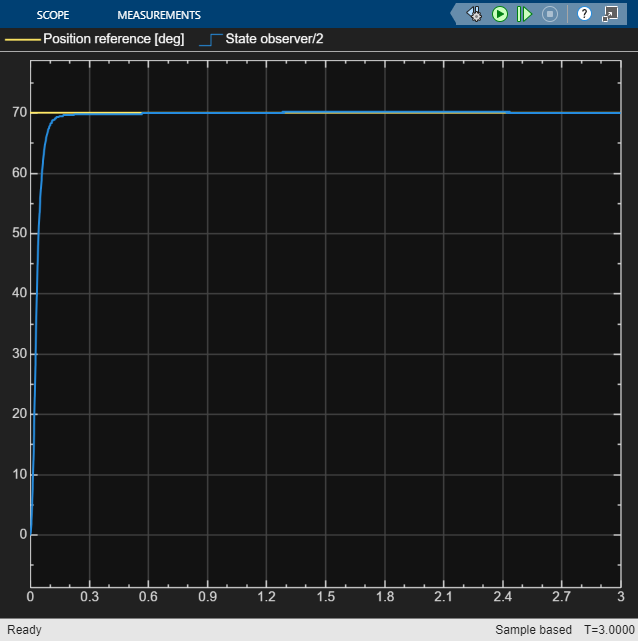

sim("challenge1_integralAction.slx");


% 1. Estrai i dati di tempo e ampiezza dall'oggetto generato da Simulink
% (Sostituisci 'dati_uscita' se hai usato un nome diverso nel blocco To Workspace)
tempo = ans.dati_uscita.Time;
ampiezza = ans.dati_uscita.Data;

% 2. Usa la funzione stepinfo per calcolare tutte le metriche della risposta
% Passiamo il segnale (ampiezza) e il vettore del tempo (tempo)
metriche_sistema = stepinfo(ampiezza, tempo);

% 3. Estrai specificamente il tempo di salita (Rise Time)
tempo_di_salita = metriche_sistema.RiseTime;
overshoot = metriche_sistema.Overshoot;
picco = metriche_sistema.Peak;
sovraelongazione = (picco-70)/70*100;

% 4. Mostra il risultato a schermo
disp(['Il tempo di salita (dal 10% al 90%) è: ', num2str(tempo_di_salita), ' secondi']);

Il tempo di salita (dal 10% al 90%) è: 0.056567 secondi


disp(['La sovraelongazione è: ', num2str(sovraelongazione), ' %']);

La sovraelongazione è: 0.28571 %


disp(['Il picco massimo è: ', num2str(picco)]);

Il picco massimo è: 70.2
